In entrambi i segnali  si hanno 400000 campioni con frequenza di campionamento di 1000Hz, quindi in totale si hanno 400 secondi di registrazione.

Si decide di elaborare i segnali utilizzando finestre di ridotte dimensioni così che sia utilizzabile un semplice detrend lineare. Le finestre (wdw) sono di 4000 campioni l' una.

load data;
wdw=4000;

Il numero di camppini è il medesimo per entrambi i segnali ecg

n_samples = length(data1);
t = 1:n_samples;
samples_wdw = n_samples/wdw;

Abbiamo implementato una funzione Detrend_Lineare che svolge le seguenti operazioni:

Attraverso la funzione reshape creiamo una matrice avente come colonne il numero di finestre e sulle righe i campioni di ogni finestra. E' stata scelta questa stuttura poiché la funzione di detrend applicata a una matrice lavora sulle colonne di essa per eliminare le oscillazioni lente del segnale. Procediamo quindi con il detrend lineare (n = 1)  di data e lo si linearizza in un unico vettore colonna.

data_detrend1 = Detrend_Lineare(data1, wdw, samples_wdw);

data_detrend2 = Detrend_Lineare(data2, wdw, samples_wdw);

Il multiplier ci permette di modificare la soglia al suo variare.

multiplier_R = 3.5;

soglia1 = find_thr(data_detrend1, multiplier_R);

soglia2 = find_thr(data_detrend2, multiplier_R);

La distanza fisiologica tra 2 picchi R è di circa mezzo secondo che corrisponde circa a 500 campioni. Un valore ragionevole di distanza minima tra i picchi R può essere quella di 400 campioni.

MinPeakDist = 400; 

[pks1, loc_pks1] = find_ecg_peak(data_detrend1, soglia1, MinPeakDist);

[pks2, loc_pks2] = find_ecg_peak(data_detrend2, soglia2, MinPeakDist);

Grafico dei segnali dopo essere stati sottoposti al detrend lineare. I picchi R sul grafico precende evidenziandoli con dei quadrati rossi.

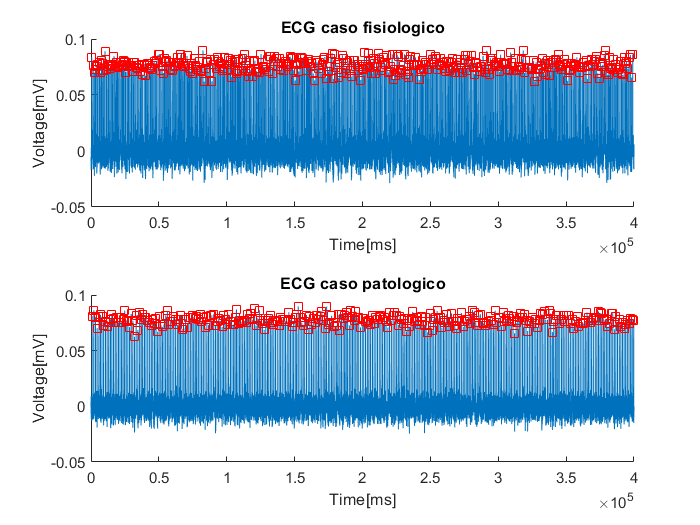

nexttile
hold on
plot(t, data_detrend1);
plot(loc_pks1, pks1,'rs');
xlabel('Time[ms]')
ylabel('Voltage[mV]')
title('ECG caso fisiologico')
hold off

nexttile
hold on
plot(t, data_detrend2); 
plot(loc_pks2, pks2,'rs'); 
xlabel('Time[ms]')
ylabel('Voltage[mV]')
title('ECG caso patologico')
hold off

Battiti al minuto

heart_rate1 = compute_heart_rate(loc_pks1); 

heart_rate2 = compute_heart_rate(loc_pks2);

Il numero di picchi R corrisponde al numero di complessi QRS e siccome questi hanno una durata media di 120 millisecondi e che la frequenza di campionamento è di 1000 Hz, allora tale intervallo temporale corrisponde a 120 campioni. Infine si sceglie un numero di campioni dispari pari a 121 per avere simmetria.

N1 = numel(pks1);  
N2 = numel(pks2);
MQ = 121 ;    
       
x=1:(MQ);

QRS1=zeros(MQ, N1); %righe: numero di campioni per finestra;   colonne: numero complessi
QRS2=zeros(MQ, N2);

C = (MQ-1)/2 + 1; % posizione dell' elemento centrale

Grafico di tutti i complessi QRS e QRS medio caso fisiologico

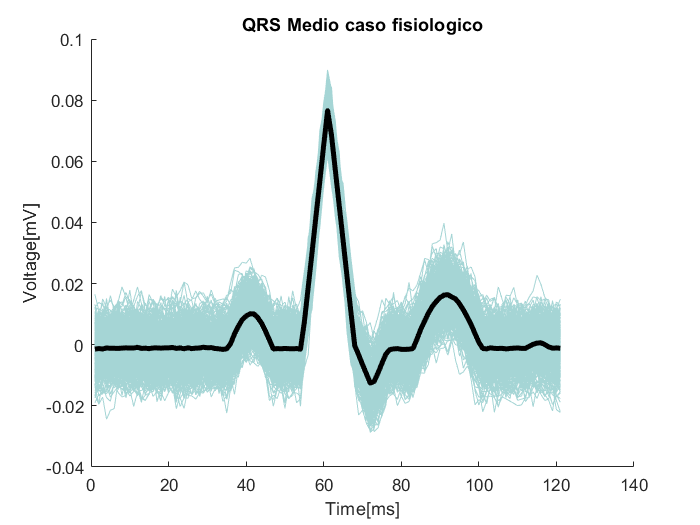

% NOTA: Abbiamo deciso di mantendere il codice e di ripeterlo nei 2 blocchi
      % di codice seguenti in quanto per creare una funzione apposita sarebbero
      % stati necessari un numero considerevole di input.

figure(3)
for k=1:N1
    for j=1:(MQ-1)/2
           QRS1(j, k)=data_detrend1(  loc_pks1(k) - C + j  );
           QRS1(C, k)=pks1(k);  % inserimento picco al centro di in ognuna delle finestre
           QRS1(j + C, k)=data_detrend1(loc_pks1(k)+j);
    end
    
    hold on;
    plot(x,QRS1(:,k),'color','#A5D5D5');
end


 QRS1_trasposto = QRS1';
 QRS1_medio= mean(QRS1_trasposto);
 
 plot(x, QRS1_medio,'black','LineWidth',3); 
 title('QRS Medio caso fisiologico')
 xlabel('Time[ms]')
 ylabel('Voltage[mV]')
 hold off

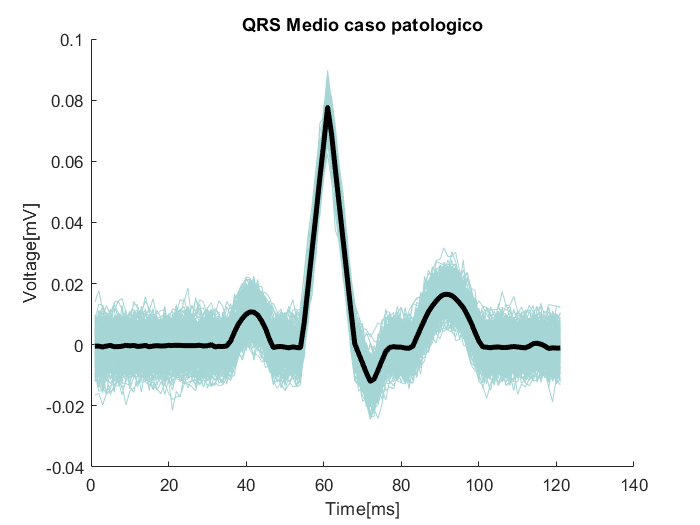

 
 figure(4)
 for k=1:N2
    for j=1:(MQ-1)/2
           QRS2(j, k)=data_detrend2(  loc_pks2(k) - C + j  );
           QRS2(C, k)=pks2(k);  % inserimento picco al centro di in ognuna delle finestre
           QRS2(j + C, k)=data_detrend2(loc_pks2(k)+j);
    end
    
    hold on;
    plot(x,QRS2(:,k),'color','#A5D5D5');
end


 QRS2_trasposto = QRS2';
 QRS2_medio= mean(QRS2_trasposto);
 
 plot(x, QRS2_medio,'black','LineWidth',3);
 title('QRS Medio caso patologico')
 xlabel('Time[ms]')
 ylabel('Voltage[mV]')
 hold off

Calcolo distanza media tra picco Q ed S.

[qrs_duration1, dist_QRS1] = mean_QRS(QRS1,C);
[qrs_duration2, dist_QRS2]= mean_QRS(QRS2,C);

Istogrammi

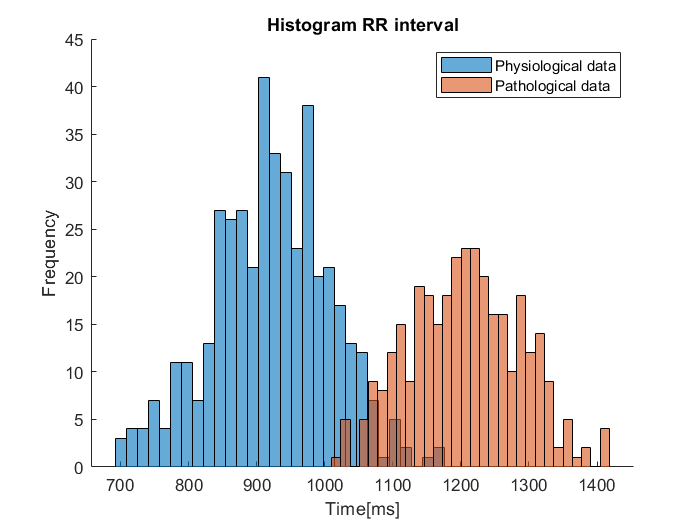

pks_bins1 = bin_edges(diff(loc_pks1),30);
pks_bins2 = bin_edges(diff(loc_pks2),30);


figure(5)
hold on
histogram(diff(loc_pks1),pks_bins1);
histogram(diff(loc_pks2),pks_bins2); 
title('Histogram RR interval')
xlabel('Time[ms]')
ylabel('Frequency')
legend('Physiological data', 'Pathological data')
hold off

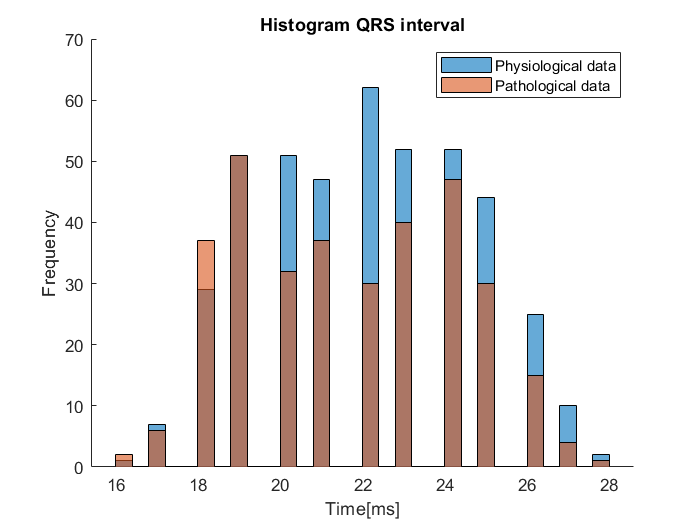

pks_bins3 = bin_edges(dist_QRS1,30);
pks_bins4 = bin_edges(dist_QRS2,30);

figure(6)
hold on
histogram(dist_QRS1,pks_bins3, "EdgeColor","black");
histogram(dist_QRS2,pks_bins4, "EdgeColor","black"); 
title('Histogram QRS interval')
xlabel('Time[ms]')
ylabel('Frequency')
legend('Physiological data', 'Pathological data')
hold off 

Funzione di detrend lineare

function data_detrend = Detrend_Lineare(data, wdw, samples_wdw)
     data = reshape(data, wdw, samples_wdw);
     data_detrend = detrend(data,1);
     data_detrend = data_detrend(:);
end

Funzione per il calcolo della soglia dei picchi al variare del multiplier.

function thr = find_thr(data, multiplier)
%compute threshold based on data mean+multiplier*std
media = mean(data);
dev_standard = std(data);
thr = media + multiplier * dev_standard;

end

Funzione per calcolare i picchi Q, R ed S.

function [pks, loc_pks] = find_ecg_peak(data, thr, MinPeakDistance)
%Find R peaks
[pks, loc_pks] = findpeaks(data,'MinPeakHeight',thr,'MinPeakDistance',MinPeakDistance);

end

Funzione per il calcolo dei battiti al minuto.

function heart_rate = compute_heart_rate(loc_pks)
% Compute heart beat rate
distanza_msec = mean(abs(diff(loc_pks))); % media della distanza tra i picchi R
                                           % espressa in millisecondi

distanza_sec = distanza_msec / 1000; % conversione da milli secondi a secondi
heart_rate = round(60 / distanza_sec); % formula vista nel corso di fisiologia
end

Funzione per il calcolo della durata del complesso QRS.

function [qrs_duration, dist_QRS] = mean_QRS(QRS, C)
% Compute QRS complex
multiplier_Q_S = -0.5; % questo parametro multiplier abbiamo verificato essere ottimo sia per i picchi Q che S
                       % ed è negativo poiché alcuni picchi Q ed S sono
                       % sotto zero

Start = 40;  % parametro che serve per stringere la finestra di campioni che consideriamo per trovare i picchi
             % Q ed S, poiché i picchi Q sono immersi nel
             % rumore il che rende difficile distinguerli.
             
Distanza_picchi = 15; % Anche in questo caso la distanza ideale trovata è la
                      % medesima per il calcolo di enrambi i picchi.
             
Q = QRS( Start:C, :);  % intervalli contenenti i picchi Q ed R
Q_inverted = -Q;       % ogni colonna contiene i picchi Q ed R del rispettivo complesso QRS
                       % invertiamo i valori del detrend per avere dei picchi Q positi per potrer
                       % usare la funzione detrend
                       

S = QRS(C:C+Start/2+1, :); % intervalli contenenti i picchi R ed S
S_inverted = -S;           % ogni colonna contiene i picchi R ed S del rispettivo complesso QRS
                           %lo invertiamo per il medesimo motivo
 
%A questo punto abbiamo 2 vettori contenenti meno campioni e invertiti

Q_vector = reshape(Q_inverted, 1, [] ); % Q_inverted scritto come vettore unico
soglia_Q = find_thr(Q_vector, multiplier_Q_S );
[pks_Q, loc_pks_Q] = find_ecg_peak(Q_vector, soglia_Q, Distanza_picchi);
 
S_vector = reshape(S_inverted, 1, []); % S_inverted scritto come vettore unico
soglia_S = find_thr(S_vector, multiplier_Q_S);
[pks_S, loc_pks_S] = find_ecg_peak(S_vector, soglia_S, Distanza_picchi);


% Per determinare la distanza QR possiamo sfruttare il fatto che conosciamo
% la posizione dei picchi R in entrambi i casi ( caso QR e caso RS)

t_Q = 1:numel(pks_Q); 
t_Q = t_Q * (C - Start + 1); % vettore che contiene le posizioni dei picchi R (caso QR)
dist_QR = t_Q - loc_pks_Q; %sottraiamo la posizione dei picchi Q alla posizione dei picchi R --> otteniamo la durata QR

t_S = 1:numel(pks_S);
t_S = (t_S * (C - Start +1)) - (C - Start);% vettore che contiene le posizioni dei picchi R (caso RS)
dist_RS =loc_pks_S -  t_S; %sottraiamo la posizione dei picchi R alla posizione dei picchi S --> otteniamo la durata RS

dist_QRS = dist_RS + dist_QR;  %Somma tra le distanze RS e QR
qrs_duration = mean(dist_QRS); % media

end

Funzione bin che ci serve per avere dei bin edges comuni che servono confrontare le pdf per entrambi i casi

function data_bins=bin_edges(data,n_bins) 
datamin=min(data);    % viene scelto il minimo come il limite inferiore
datamax=max(data);    % viene scelto il massimo come limite superiore
data_bins=linspace(datamin,datamax,(n_bins+1));  % per come vengono definiti i bin ne viene perso uno rispetto al numero di elementi totali e va aggiunto (+1)
end